%Reading the point cloud data
lasReader = lasFileReader("points (1).laz");
ptCloud = readPointCloud(lasReader);

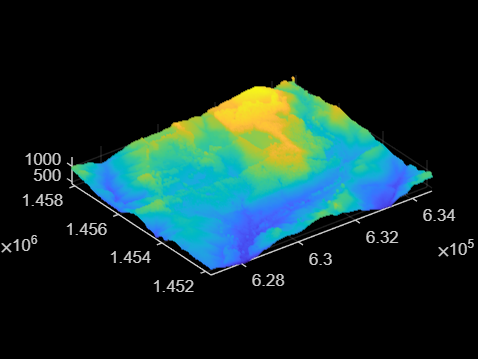

%Visualising
figure
pcshow(ptCloud.Location)


%Also be visualised using lidarViewer tool, type the command lidarViewer in
%command window 

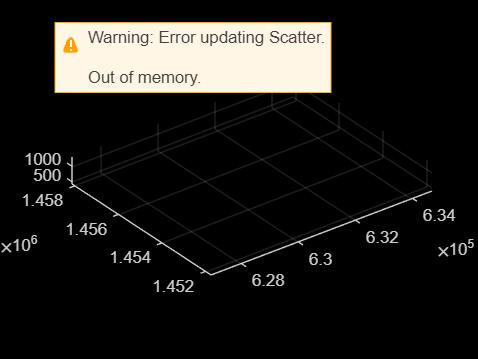

%Downsampling (Set a grid size) and Visualise
gridStep = 0.1;
ptCloudA = pcdownsample(ptCloud,'gridAverage',gridStep);
figure
pcshow(ptCloudA);

% Removal of redundant points 
ptCloud = pointCloud(ones(100,3));
gridStep = 0.01;
ptCloudOut = pcdownsample(ptCloud,'gridAverage',gridStep)

%denoising and outlier removal
ptCloudB = pcdenoise(ptCloudA);
figure;
pcshow(ptCloudB);
title('Denoised Data');

% Removal of invalid points 
ptCloudOut = removeInvalidPoints(ptCloud);

%Registration of point clouds
ld = load('livingRoom.mat');
movingPtCloud = ld.livingRoomData{1};
fixedPtCloud = ld.livingRoomData{2};
figure
pcshowpair(movingPtCloud,fixedPtCloud,'VerticalAxis','Y','VerticalAxisDir','Down')

% Detecting features, (ground and non-ground)
